% paths
if ispc
    path = ("C:\Users\BrainMaker\commsubspace\hash");
elseif ismac
    path = "~/Data/commsubspace/hash";
end
addpath(path)

addpath(genpath('utils')); % all folders in utils added, including semedo code

% load
load("Megatable.mat");

% TABLE : ACQUIRE RUNS
% ----------------------
% Determine keys to use : you can use this string to arbitrarily select rows
%   each item of the filtstring is a property to select. $x pulls the x
%   column and applies the test shown
filtstring = ["ismember($animal, [""JS21"", ""JS17"", ""JS14"",""JS13"", ""ER1""])",...
              "$generateH==""fromWpli  fromRipTime""", ...
              "$spikeBinSize==0.15",...
              "$numPartition==50",...
              "$quantileToMakeWindows == 0.85",...
              "all(cat(1,$winSize{:})==[-0.15,0.15],2)"];
% Get the proper keys
matching_runs = query.getHashed_stringFilt(TABLE, filtstring)

matching_runs = 5×21 table
    animal           generateH           samplingRate    spikeBinSize    timesPerTrial      winSize       sourceArea    equalWindowsAcrossPatterns    singleControl    numPartition    binsToMatchFR    quantileToMakeWindows    preProcess_FilterLowFR    preProcess_matchingDiscreteFR    shortedRippleWindow    generateFromRipTimes      timestamp        hash       numWindowsCut      cutoffs       optimizationResult
    ______    _______________________    ____________    ____________    _____________    ____________

keys = matching_runs.hash;

% Load up combined pattern data
[Patterns, otherData] = query.combinePatterns(keys);

Loading keys:  000%  |                                            | 0/5 [00:00:00<Inf:NaN:NaN, Inf it/s]


Option = otherData{1}.Option;

% The different keys loaded will actually collapse into the partition
% dimenion
newSize = size(Patterns);
newSize = [prod(newSize(1:2)), newSize(3:end)];
Patterns = reshape(Patterns, newSize);

% OPTIONS : ACQUIRE OPTION
% ----------------------
nPartition = Option.numPartition;
% HARDish-CODED PROPERTIES
nPatterns = 3;
numResult = 6;
nSource = size(Patterns(1,1,1).X_source,1);
nTarget = size(Patterns(1,1,1).X_target,1);
numDimsUsedForPrediction = 1:min(nSource, nTarget);

Figure 2A: Cofiring in source and target

Figure 2B: Prediction Performance

Figure 4A/B: Results from rank regress

Figure 4C: How optimal number of predicitive dimensions compare between hpc and pfc

Figure 6: removing predicitive dimensions from both sources

Figure 7: Dominant dimension prediction vs. regress prediction

% basic structures and stats

% Patterns = table2array(queryresult(1,"Patterntable"));
% Patterns = reshape(table2array(Patterns), [10,2,4]);

if Option.sourceArea == "CA1"
    source = "hpc";
    target = "pfc";
    hpc = 1;
    pfc = 2;
else
    source = "pfc";
    target = "hpc";
    hpc = 2;
    pfc = 1;
end

[nPartitions, nDirections, nPatterns] = size(Patterns);
nPatterns = 3; % single control

% Options = table2array(queryresult(1,"Optiontable"));
nSource = size(Patterns(10,2,1).X_source,1);
nTarget = size(Patterns(10,2,1).X_target,1);
patternnames = ["theta", "delta", "ripples"];

## Figure 2

#### A: How pairs of neuron in source/target co-fire

path2 = "C:\Users\BrainMaker\MATLAB Drive\Shared";
cd(path2)
load("cofiring.mat");

numPairsPerPattern = (nSource+nTarget)^2 - nSource^2 - nTarget^2;

% hetroregion: target and source different, homoregion: target and source
% same
withpfc_pairs = zeros(nPatterns, numPairsPerPattern);
withhpc_pairs = zeros(nPatterns, numPairsPerPattern);

all_pairs_withpfc = [];
all_pairs_withhpc = [];

mean_corrwithpfc = [];
mean_corrwithhpc = [];

mean_withhpccorr_pattern = zeros(1,nPatterns);
mean_withpfccorr_pattern = zeros(1,nPatterns);

std_corrwithhpc = [];
std_corrwithpfc = [];


for p = 1:10
    for i = 1:nPatterns*2
        curr_source = Patterns(p,1,i).X_source';
        
        curr_HPC = Patterns(p,hpc,i).X_target';
        curr_PFC = Patterns(p,pfc,i).X_target';
        
        linearized_withhpc = plots.calculatePatternCofiring(curr_source, curr_HPC);
        linearized_withpfc = plots.calculatePatternCofiring(curr_source, curr_PFC);
        
        all_pairs_withhpc = [all_pairs_withhpc, linearized_withhpc];
        all_pairs_withpfc = [all_pairs_withpfc, linearized_withpfc];
        
        withpfc_pairs(i,:) = linearized_withpfc;
        withhpc_pairs(i,:) = linearized_withhpc;
        
        mean_withhpccorr_pattern(i) = mean(linearized_withhpc(~isnan(linearized_withhpc)));
        mean_withpfccorr_pattern(i) = mean(linearized_withpfc(~isnan(linearized_withpfc)));
    end
    cur_mean_withhpc = mean(all_pairs_withhpc(~isnan(all_pairs_withhpc)));
    cur_std_withhpc = std(all_pairs_withhpc(~isnan(all_pairs_withhpc)));
    
    cur_mean_withpfc = mean(all_pairs_withpfc(~isnan(all_pairs_withpfc)));
    cur_std_withpfc = std(all_pairs_withpfc(~isnan(all_pairs_withpfc)));
    
    mean_corrwithhpc = [mean_corrwithhpc, cur_mean_withhpc];
    mean_corrwithpfc = [mean_corrwithpfc, cur_mean_withpfc];
    
    std_corrwithhpc = [std_corrwithhpc, cur_mean_withhpc];
    std_corrwithpfc = [std_corrwithpfc, cur_mean_withpfc];
    
end
% hh_pairs_patterns = hh_pairs_patterns(~all(isnan(hh_pairs_patterns), 2))
% hh_pairs_patterns(~isnan(hh_pairs_patterns))
% mean_patternCofiring = mean(hh_pairs_patterns,2);



The co-firing of hpc and pfc neurons during different activity patterns, with average plotted

figure(499)
clf
h_corrdiff = zeros(1,nPatterns);
p_corrdiff = zeros(1,nPatterns);
for i = 1:3
    subplot(3,1,i)
    cofiring_hh = histogram(withhpc_pairs(i,:));
    hold on
    cofiring_hp = histogram(withpfc_pairs(i,:));
    
    title(patternnames(i))
    ylabel("pairs")
    
    hold on
    avg_hh=line([mean_withhpccorr_pattern(i),mean_withhpccorr_pattern(i)],[0 max(cofiring_hh.Values)]);
    avg_hh.LineStyle = ':'; % Make line dotted
    avg_hh.LineWidth = 2;  % Thicken the line
    avg_hh.Color = 'blue';
    avg.hh.DisplayName = "hpc-hpc corfiring mean";
    
    hold on
    avg_hp=line([mean_withpfccorr_pattern(i),mean_withpfccorr_pattern(i)],[0 max(cofiring_hh.Values)]);
    avg_hp.LineStyle = ':'; % Make line dotted
    avg_hp.LineWidth = 2;  % Thicken the line
    avg_hp.Color = 'red'; % Color it black
    avg.hh.DisplayName = "hpc-pfc corfiring mean";
    
    if source == "hpc"
        legend("hpc-hpc","hpc-pfc")
    else
        legend("pfc-hpc","pfc-pfc")
    end
    
    xlabel("pairwise correlation")
    [h_corrdiff(i),p_corrdiff(i)] = kstest2(withhpc_pairs(i,:), withpfc_pairs(i,:));
    
end

the difference in cofiring between hpc-hpc pairs and hpc-pfc pairs are significant for all the activity patterns

% How about just put all the patterns together?
figure (500)
subplot(2,1,1)
ax1 = nexttile;
hist_withpfc = histogram(all_pairs_withhpc)
ylabel("Pairs")
title ("HPC-HPC")
example_mean_corr_withhpc = mean_corrwithhpc(1);
example_std_corr_withhpc = std_corrwithhpc(1);

hold on
lineObject=line([example_mean_corr_withhpc,example_mean_corr_withhpc],[0 max(hist_withpfc.Values)]);
lineObject.LineStyle = ':'; % Make line dotted
lineObject.LineWidth = 2;  % Thicken the line
lineObject.Color = 'black'; % Color it black
subplot(2,1,2)
ax2 = nexttile;
hist_hp = histogram(all_pairs_withpfc)
ylabel("Pairs")
title ("HPC-PFC")
example_mean_corr_withpfc = mean_corrwithpfc(1);
example_std_corr_withpfc = std_corrwithpfc(1);

lineObject=line([example_mean_corr_withpfc,example_mean_corr_withpfc],[0 max(hist_hp.Values)]);
lineObject.LineStyle = ':'; % Make line dotted
lineObject.LineWidth = 2;  % Thicken the line
lineObject.Color = 'black'; % Color it black
xlabel("Pairwise correlation")
linkaxes([ax1,ax2],'x');
[h_corrdiff,p_corrdiff] = kstest2(all_pairs_withpfc,all_pairs_withhpc);

% saving meaningful stats and the corresponding Option fields in a csv
cofiring = table(mean(mean_corrwithhpc), mean(std_corrwithhpc), mean(mean_corrwithpfc), mean(std_corrwithpfc), h_corrdiff, p_corrdiff)
cofiringRow = table(cofiring, key);

cofiringstats = [cofiringstats; cofiringRow];

save('cofiring', 'cofiringstats')

% print stats
formatSpec1 = "%s: %0.3f±%0.3f";

sprintf(formatSpec1,Patterns(1,1).directionality,mean(mean_corrwithhpc),mean(std_corrwithhpc))
sprintf(formatSpec1,Patterns(2,1).directionality,mean(mean_corrwithpfc),mean(std_corrwithpfc))
disp(p_corrdiff)

Average correlation:

HPC-HPC: 0.1413 ± 0.1047

HPC-PFC: 0.0397 ± 0.0509

p < 0.01 for difference between HPC-PFC and HPC-HPC.

*"These weak correlations indicate that only a small fraction of a neuron’s response variability*

*can be explained by another individual neuron"*

#### B: Prediction Performance

load("prediction.mat");
figure(600), clf
% how well a single neuron can predict stuff

single_pred_with_hpc = [];
single_pred_with_pfc = [];

patternPerformance_pfc = zeros(nPatterns, nPartitions); % prediction of
patternPerformance_hpc = zeros(nPatterns, nPartitions);
% useSinglePrediction = true;
for p = 1:nPartitions
    for i = 1:nPatterns
        curr_source = Patterns(p,1,i).X_source';
        nSource = size(curr_source,2);
        for d = 1:2
            curr_target = Patterns(p,d,i).X_target';
            for k = 1:nSource
                curr_singleB = Patterns(p,d,i).rankRegress.singlesource_B{k};
                if ~isempty(curr_singleB)
                    curr_singlesource = curr_source(:,k);
                    [singlepattern,~] = plots.calculatePredictionPerformance(curr_singlesource, curr_target, curr_singleB);
                    if d == 1
                        [single_pred_with_hpc] = [single_pred_with_hpc singlepattern];
                    else
                        [single_pred_with_pfc] = [single_pred_with_pfc singlepattern];
                    end
                end
            end
        end
    end
end
median_singlehh = median(single_pred_with_hpc(~isnan(single_pred_with_hpc)));
temp1 = single_pred_with_pfc(~isinf(single_pred_with_pfc));
temp1 = temp1(~isnan(temp1));
median_singlehp = median(temp1);


r_square_withhpc = [];
r_square_withpfc = [];

r_withhpc_patterns = zeros(nPatterns, nTarget*nPartitions);
r_withpfc_patterns = zeros(nPatterns, nTarget*nPartitions);
%
% mean_hpcpred_pattern = zeros(1,nPatterns);
% mean_pfcpred_pattern = zeros(1,nPatterns);

for p = 1:10
    for i = 1:nPatterns
        curr_source = (Patterns(p,1,i).X_source)';
        curr_targethpc = (Patterns(p,hpc,i).X_target)';
        curr_targetpfc = (Patterns(p,pfc,i).X_target)';
        
        curr_B_hpc = Patterns(p,hpc,i).rankRegress.B;
        curr_B_pfc = Patterns(p,pfc,i).rankRegress.B;
        
        [patternhpc, meanhpc, ~] = plots.calculatePredictionPerformance(curr_source, curr_targethpc, curr_B_hpc);
        [patternpfc, meanpfc, ~] = plots.calculatePredictionPerformance(curr_source, curr_targetpfc, curr_B_pfc);
        
        r_square_withhpc = [r_square_withhpc patternhpc];
        r_square_withpfc = [r_square_withpfc patternpfc];
        
        patternPerformance_hpc(i,p) = meanhpc;
        
        patternPerformance_pfc(i,p) = meanpfc;
        
        r_withpfc_patterns(i,(p-1)*nTarget+1:p*nTarget) = patternpfc;
        r_withhpc_patterns(i,(p-1)*nTarget+1:p*nTarget) = patternhpc;
        
    end
    
end

% pattern_mean_withhpc = mean(patternPerformance_hpc(~isnan(patternPerformance_hpc)),1);
% pattern_mean_withpfc = mean(patternPerformance_pfc(~isnan(patternPerformance_pfc)),2);

figure(233)
clf
h_pred = zeros(1,nPatterns);
p_pred = zeros(1,nPatterns);
meanpred_hpc = zeros(1,nPatterns);
meanpred_pfc = zeros(1,nPatterns);
for i = 1:nPatterns
    subplot(3,1,i)
    %     curr_hh = r_square_hh_patterns(i,:);
    %     temp_hh = curr_hh(curr_hh~=-10000);
    %     histogram(temp_hh);
    curr1 = r_withhpc_patterns(i,:);
    indices1 = intersect(find(curr1>0), find(~isnan(curr1)));
    
    histogram(curr1(indices1));
    hold on
    %     curr_hp = r_square_hp_patterns(i,:);
    %     temp_hp = curr_hp(curr_hp~=-10000);
    %     histogram(temp_hp);
    curr2 = r_withpfc_patterns(i,:);
    indices2 = intersect(find(curr2>0), find(~isnan(curr2)));
    
    histogram(curr2(indices2));
    %     histogram(r_withpfc_patterns(i,:));
    
    pattern_mean_withhpc = mean(patternPerformance_hpc(i,:));
    pattern_mean_withpfc = mean(patternPerformance_pfc(i,:));
    meanpred_hpc(i) = pattern_mean_withhpc;
    meanpred_pfc(i) = pattern_mean_withpfc;
    hold on
    avg_hh=line([pattern_mean_withhpc,pattern_mean_withhpc],[0 max(cofiring_hh.Values)]);
    avg_hh.LineStyle = ':'; % Make line dotted
    avg_hh.LineWidth = 2;  % Thicken the line
    avg_hh.Color = 'blue';
    
    hold on
    avg_hp=line([pattern_mean_withpfc,pattern_mean_withpfc],[0 max(cofiring_hh.Values)]);
    avg_hp.LineStyle = ':'; % Make line dotted
    avg_hp.LineWidth = 2;  % Thicken the line
    avg_hp.Color = 'red'; % Color it black
    
    
    [h_pred(i),p_pred(i)] = kstest2(withhpc_pairs(i,:), withpfc_pairs(i,:));
    ylabel("data sets")
    title(patternnames(i));
    if source == "hpc"
        legend("hpc-hpc","hpc-pfc")
    else
        legend("pfc-hpc","pfc-pfc")
    end
end

[h_hpc, p_hpc] = kstest2(meanpred_hpc, mean_withhpccorr_pattern)
[h_pfc, p_pfc] = kstest2(meanpred_pfc, mean_withpfccorr_pattern)

mean_withhpc = mean(r_square_withhpc(intersect(~isinf(r_square_withhpc), ~isnan(r_square_withhpc))));
std_withhpc  = std(r_square_withhpc(intersect(~isinf(r_square_withhpc), ~isnan(r_square_withhpc))));

mean_withpfc = mean(r_square_withpfc(intersect(~isinf(r_square_withpfc), ~isnan(r_square_withpfc))));
std_withpfc = std(r_square_withpfc(intersect(~isinf(r_square_withpfc), ~isnan(r_square_withpfc))));

subplot(2,1,1)
ax1 = nexttile;
hist_withpfc = histogram(r_square_withhpc,25)
ylabel("Data Sets")
title ("source predicting HPC targets")
lineObject=line([mean_withhpc,mean_withhpc],[0 max(hist_withpfc.Values)]);
lineObject.LineStyle = ':'; % Make line dotted
lineObject.LineWidth = 2;  % Thicken the line
lineObject.Color = 'black'; % Color it black

lineObject2 = line([median_singlehh,median_singlehh],[0 max(hist_withpfc.Values)]);
lineObject2.LineWidth = 3;
lineObject2.Color = 'blue';


subplot(2,1,2)
ax2 = nexttile;
hist_hp = histogram(r_square_withpfc,25)
% prediction performance from hpc to pfc cells
ylabel("Data Sets")
title ("source preding PFC targets")
xlabel("Performance")
linkaxes([ax1,ax2],'x');
lineObject=line([mean_withpfc,mean_withpfc],[0 max(hist_hp.Values)]);
lineObject.LineStyle = ':'; % Make line dotted
lineObject.LineWidth = 2;  % Thicken the line
lineObject.Color = 'black'; % Color it black

lineObject2 = line([median_singlehp,median_singlehp],[0 max(hist_hp.Values)]);
lineObject2.LineWidth = 3;  % Thicken the line
lineObject2.Color = 'blue'; % Color it black


figure(601)
clf
for i = 1:nPatterns
    subplot(3,1,i)
    plot(patternPerformance_pfc(i,:));
    hold on
    plot(patternPerformance_hpc(i,:));
    
    legend("pfc","hpc")
    % how to interpret nans
end


% saving meaningful stats and the corresponding Option fields in a csv
Predictiontable  = table(mean_withhpc, std_withhpc, mean_withpfc, std_withpfc)
predictionRow = table(Predictiontable, key)
predictionstats = [predictionstats; predictionRow];
save('prediction','predictionstats');


% print stats
formatSpec1 = "%s: %0.3f±%0.3f";
disp("Prediction Performance on Average")
sprintf(formatSpec1,Patterns(1,1).directionality,mean_withhpc,std_withhpc)
sprintf(formatSpec1,Patterns(2,1).directionality,mean_withpfc,std_withpfc)
if useSinglePrediction
    disp('single source prediction median')
    formatSpec2 = "%s: %0.5e";
    sprintf(formatSpec2,Patterns(1,1).directionality,median_singlehh)
    sprintf(formatSpec2,Patterns(1,2).directionality,median_singlehp)
    
end

## Figure 4


numUsedForPrediction = min(nTarget,nSource);
% make the averaged version
curr_cvLoss = cell(10,2,3);
curr_rrDim = cell(10,2,3);
for p = 1:10
    for i = 1:nPatterns
        for j = 1:2
            curr_cvLoss{p,j,i} = Patterns(p,j,i).rankRegress.cvLoss;
            curr_rrDim{p,j,i} = Patterns(p,j,i).rankRegress.optDimReducedRankRegress;
        end
    end
end

figure(700)
clf
full_model_performance = [];

for i = 1:nPatterns
    for j = 1:2
        subplot(3,2,2*(i-1)+j)
        
        full_model = plots.plotPredictiveDimensions(numUsedForPrediction,...
            curr_cvLoss(:,j,i), "optDim", curr_rrDim(:,j,i),"mode", "rr");
        
        
        full_model_performance = [full_model_performance, full_model];
        xlim([0,12.5])
        hold on
        
        plot(1, full_model,'^');
        ylim([0, full_model+0.1])
        if j == 1
            ax1 = gca;
        else
            ax2 = gca;
        end
        title([Patterns(p,j,i).name Patterns(p,j,i).directionality])
    end
    linkaxes([ax1,ax2],'y')
    
end
animalname = Option.animal;
FullPerformancerow = [{Option.generateH}, {abs(Option.winSize{1}(1)*2)},table(full_model_performance)]
FullPerformancerow = [table(animalname), FullPerformancerow]


#### 4C

#### How optimal number of predicitive dimensions compare between hpc and pfc (this is gathered over animals)

result = query.getHashed("sourceArea","CA1")



numResultsToExamine = size(result,1);
ratios = zeros(3,numResultsToExamine);
hpcDims = zeros(3,numResultsToExamine);
pfcDims = zeros(3,numResultsToExamine);

for i = 1:numResultsToExamine
    %     currPatterns = table2array(table2array(result(i,2)));
    %     currPatterns = reshape(currPatterns, [10,2,4]);
    
    load(result(i,:))
    
    temp1 = zeros(3,nPartitions);
    temp2 = zeros(3,nPartitions);
    temp3 = zeros(3,nPartitions);
    for j = 1:nPartitions
        for k = 1:nPatterns
            temp2(k,j) = Patterns(j,hpc,k).rankRegress.optDimReducedRankRegress;
            temp3(k,j) = Patterns(j,pfc,k).rankRegress.optDimReducedRankRegress;
            temp1(k,:) = temp2(k,:)./temp3(k,:);
        end
        
    end
    
    ratios(:,i) = mean(temp1,2);
    hpcDims(:,i) = mean(temp2,2);
    pfcDims(:,i) = mean(temp3,2);
end




figure(800)

clf
for i = 1:nPatterns
    subplot(1,3,i)
    x = 1:nTarget;
    plot(x,x)
    hold on
    scatter(hpcDims(i,:), pfcDims(i,:));
    ylabel("PFC Predictive Dims")
    xlabel("HPC Predictive Dims")
    title(patternnames(i))
    axis square
end

figure (801)
diff = hpcDims-pfcDims;
histogram(diff)

## Figure 6

**Pattern Specific **

% Let's get that dimension to use for all of these
tmp = nd.fieldGet(Patterns,'rankRegress');
optDim = nd.fieldGet(tmp,'optDimReducedRankRegress');
optDim = floor(median(optDim, 1));
optDim = max(optDim,[],'all');
% Run all of them
rt = table();

for iPartition = progress(1:size(Patterns,1),'Title','iPartition')
    for baseDirection = 1:size(Patterns,2)
    for removeDirection = 1:size(Patterns,2)
        for basePattern = 1:numel(patternnames)
        for removePattern = 1:numel(patternnames)
            
            % Base patterns
            X_source = Patterns(iPartition, baseDirection, basePattern).X_source;
            X_target = Patterns(iPartition, baseDirection, basePattern).X_target;
            cvLoss = Patterns(iPartition,   baseDirection, basePattern).rankRegress.cvLoss;
            numDimsUsedForPrediction = 1:size(cvLoss,2);
            % Remove patterns
            B_ = Patterns(iPartition, removeDirection, removePattern).rankRegress.B_;
            % Run dim removal
            [performance,fullmodel] = plots.sequentialRemovePredDims(X_source, X_target, B_, optDim,...
                cvLoss, numDimsUsedForPrediction, "normalized", false);
            
            
            T = table(iPartition, baseDirection, removeDirection, patternnames(basePattern), patternnames(removePattern),fullmodel,...
                        'VariableNames',{'partition','baseDirection','removeDirection','basePattern','removePattern','fullmodel'});
            T = repmat(T,numel(performance),1);
            T.dimensionRemoved = (0:numel(performance(:))-1)';
            T.performance = performance(:);
            rt = [rt; T];
        end
        end
    end
    end
end

iPartition:  000%  |                                            | 0/2 [00:00:00<Inf:NaN:NaN, Inf it/s]


rt.sameDirection = rt.baseDirection == rt.removeDirection;
dirlabel = ["remove other area","remove same area"]';
rt.sameDirectionLabel = dirlabel(rt.sameDirection+1);
dirlabel = ["hpc-hpc","hpc-pfc"]';
rt.targetArea = dirlabel(rt.baseDirection);

Index exceeds the number of array elements (2).

rt.removeTargetArea = dirlabel(rt.removeDirection);
rt.basePatternLabel = rt.basePattern.replace('theta','$\theta$').replace('delta','$\delta$').replace('ripple','SPW-R');
rt.removePatternLabel = rt.removePattern.replace('theta','$\theta$').replace('delta','$\delta$').replace('ripple','SPW-R');

###  Remove tuples of (targetArea,pattern) from a given (targetArea, pattern)

figure;
g = gramm(...
    'x',rt.dimensionRemoved, ...
    'y', rt.performance, ...
    'color', categorical(rt.removePattern), ...
    'lightness', categorical(rt.sameDirectionLabel),...
    'linestyle', categorical(rt.sameDirectionLabel));
g = g.facet_grid(categorical(rt.basePatternLabel), categorical(rt.targetArea));

Unrecognized table variable name 'basePatternLabel'.

g = g.stat_summary('geom','line');
g = g.stat_summary('geom','point');
g = g.stat_summary('geom','errorbar');
g = g.stat_summary('geom','area');
g.set_text_options("interpreter",'latex');
g = g.set_names('x','dims removed',...
    'y','peformance',...
    'column','Interaction',...
    'row','Pattern', ...
    'color','Pattern dims removed',...
    'lightness',"Remove Same/Different"+newline+"Pred. Target",...
    'linestyle',"Remove Same/Different"+ newline+"Pred. Target");
g.draw();
warning off; set(g.facet_axes_handles, 'yscale','log'); warning on;

### Remove pattern from same target area

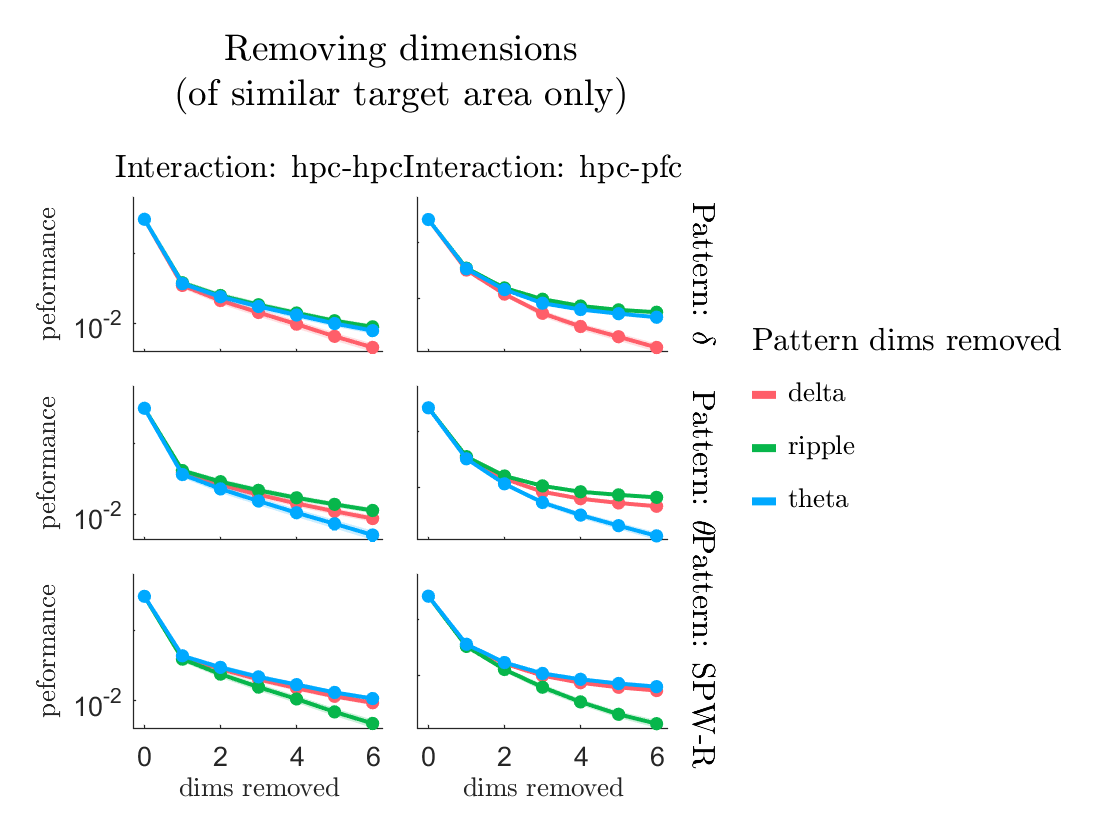

figure;
g = gramm(...
    'x',rt.dimensionRemoved, ...
    'y', rt.performance, ...
    'color', categorical(rt.removePattern), ...
    'subset',rt.sameDirection);
g = g.facet_grid(categorical(rt.basePatternLabel), categorical(rt.targetArea));
g = g.stat_summary('geom','line');
g = g.stat_summary('geom','point');
g = g.stat_summary('geom','errorbar');
g = g.stat_summary('geom','area');
g.set_text_options("interpreter",'latex');
g=g.set_title("Removing dimensions" + newline + "(of similar target area only)");
g = g.set_names('x','dims removed',...
    'y','peformance',...
    'column','Interaction',...
    'row','Pattern', ...
    'color','Pattern dims removed');
g.draw();
warning off; set(g.facet_axes_handles, 'yscale','log'); warning on;

figure;
g = gramm(...
    'x',rt.dimensionRemoved, ...
    'y', rt.performance, ...
    'color', categorical(rt.removePattern), ...
    'subset',~rt.sameDirection);
g = g.facet_grid(categorical(rt.basePatternLabel), categorical(rt.targetArea));
g = g.stat_summary('geom','line');
g = g.stat_summary('geom','point');
g = g.stat_summary('geom','errorbar');
g = g.stat_summary('geom','area');
g = g.set_color_options('lightness',200);
g.set_text_options("interpreter",'latex');
g = g.set_names('x','dims removed',...
    'y','peformance',...
    'column','Interaction',...
    'row','Pattern', ...
    'color','Pattern dims removed');
g=g.set_title('Removing different only')

g =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


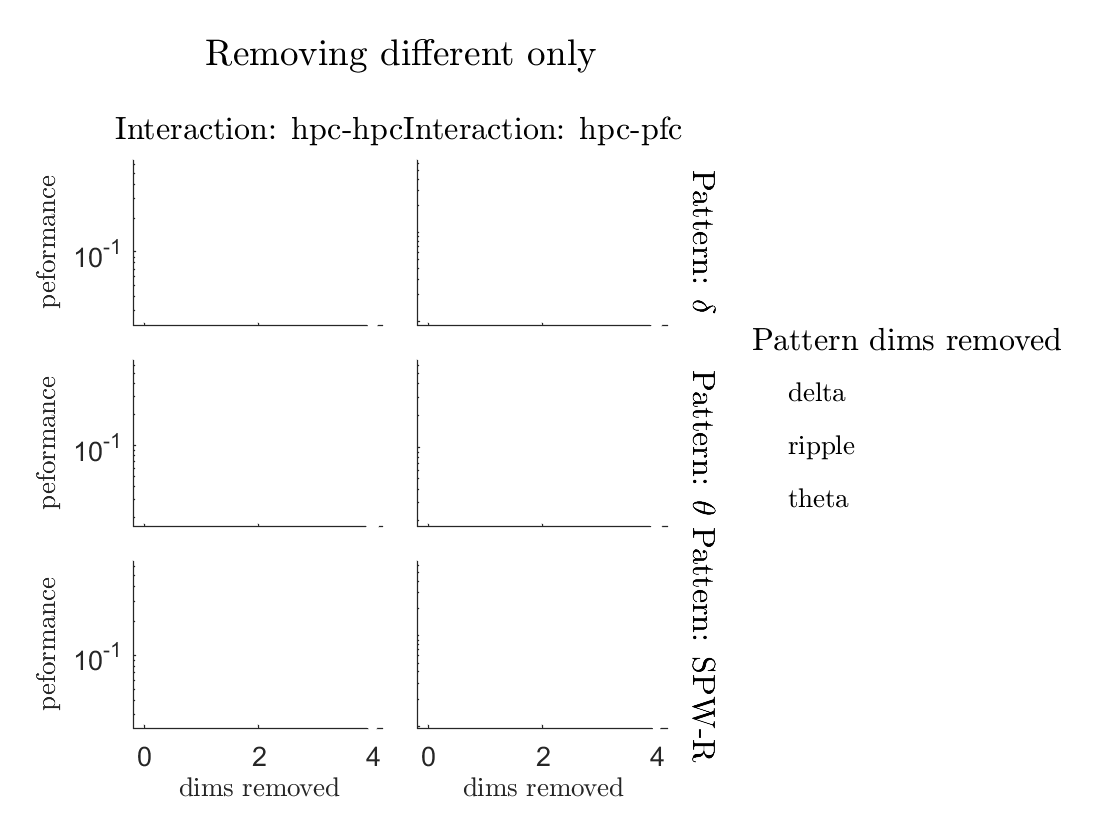

g.draw();
warning off; set(g.facet_axes_handles, 'yscale','log'); warning on;

### Overall target removal

figure;
g = gramm(...
    'x',rt.dimensionRemoved, ...
    'marker', rt.targetArea,...
    'y', rt.performance, ...
    'color', categorical(rt.sameDirectionLabel),'subset',~rt.sameDirection);
g = g.facet_grid([],categorical(rt.targetArea));
g = g.stat_summary('geom','line');
g = g.stat_summary('geom','point');
g = g.stat_summary('geom','errorbar');
g = g.stat_summary('geom','area');
g = g.set_color_options('chroma',0,'lightness',30);
g.set_text_options("interpreter",'latex');
g = g.set_names('x','dims removed',...
    'y','peformance',...
    'column','Interaction',...
    'row','Pattern', ...
    'color','Brain area removed');
snapnow;
g=g.update('subset',rt.sameDirection);
%g = g.facet_grid([],categorical(rt.targetArea));
g = g.stat_summary('geom','line');
g = g.stat_summary('geom','point');
g = g.stat_summary('geom','errorbar');
g = g.stat_summary('geom','area');
g = g.set_color_options(); % Restore default color
g.draw();
warning off; set(g.facet_axes_handles, 'yscale','log'); warning on;

Now let's see how similar those curves are in dimension reduced space

unstack(rt, '');

## Figure 7

#### A: Dominant dimension predicitions

numUsedForPrediction = min(nTarget,nSource);
% make the averaged version
curr_cvLoss_fa = cell(10,2,3);
curr_qOptDim = cell(10,2,3);
curr_cvLoss_rr = cell(10,2,3);
curr_rrOptDim = cell(10,2,3);
for p = 1:10
    for i = 1:nPatterns
        for j = 1:2
            if ~Patterns(p,j,i).singularWarning
                curr_cvLoss_fa{p,j,i} = Patterns(p,j,i).factorAnalysis.cvLoss;
                curr_qOptDim{p,j,i} = Patterns(p,j,i).factorAnalysis.optDimFactorRegress;
                
                curr_cvLoss_rr{p,j,i} = Patterns(p,j,i).rankRegress.cvLoss;
                curr_rrOptDim{p,j,i} = Patterns(p,j,i).rankRegress.optDimReducedRankRegress;
            end
        end
    end
end

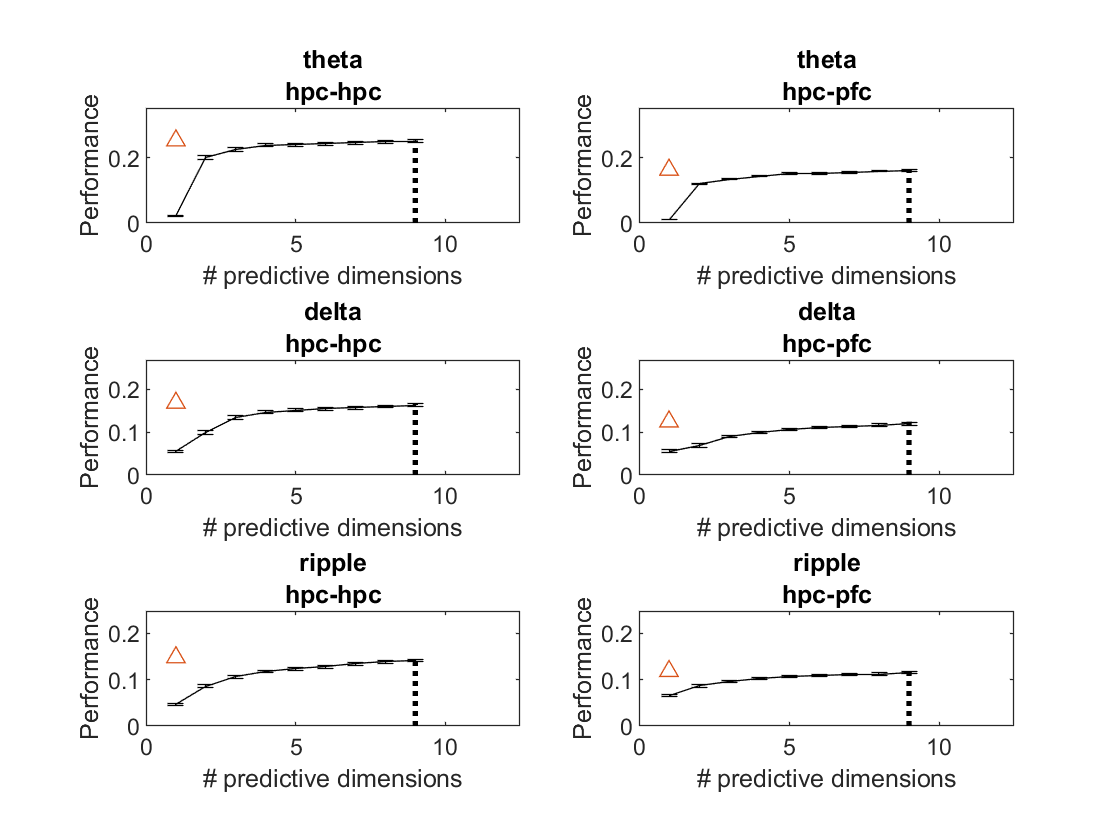

figure(750)
clf
full_model_performance_fa = [];

for i = 1:nPatterns
    for j = 1:2
        subplot(3,2,2*(i-1)+j)
        
        full_model_fa = plots.plotPredictiveDimensions(numUsedForPrediction,curr_cvLoss_fa(:,j,i),'optDim',curr_qOptDim, ...
            "mode", "fa");
        
        full_model_performance_fa = [full_model_performance_fa, full_model];
        xlim([0,12.5])
        hold on
        
        plot(1, full_model_fa,'^');
        ylim([0, full_model_fa+0.1])
        
        hold on
        full_model_rr = plots.plotPredictiveDimensions(numUsedForPrediction,curr_cvLoss_rr(:,j,i),'optDim',curr_rrOptDim, ...
            "mode", "rr", "color","blue");
        if j == 1
            ax1 = gca;
        else
            ax2 = gca;
        end 
        title([Patterns(p,j,i).name Patterns(p,j,i).directionality])
    end
    linkaxes([ax1,ax2],'y')
    
end